% Clear the workspace and console
clc; clear;

% 读取原始图像数据
origin = imread("baby.jpg");

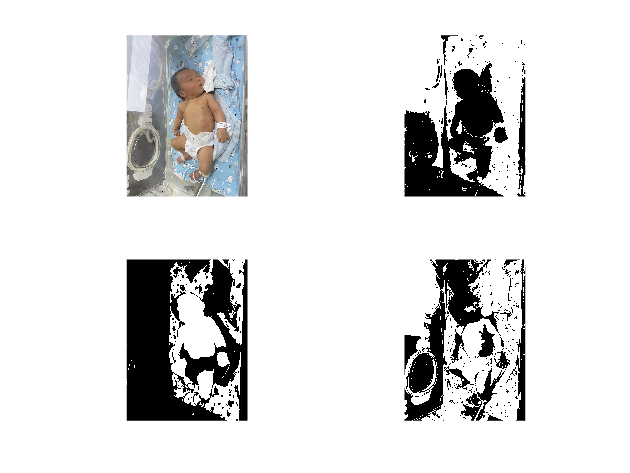

R = origin(:,:,1);
G = origin(:,:,2);
B = origin(:,:,3);

for i=1:1:840
 for j=1:1:630
 maxMatrix(i,j) = max(max(R(i,j),G(i,j)),B(i,j));
 minMatrix(i,j) = min(min(R(i,j),G(i,j)),B(i,j));
 if maxMatrix(i,j) == 0
    S(i,j) = 0;
 else
    S(i,j) = (double(maxMatrix(i,j))- double(minMatrix(i,j))) / double(maxMatrix(i,j));
 end

 if maxMatrix(i,j) == R(i,j) & G(i,j) >= B(i,j)
     H(i,j) = 60*((G(i,j) - B(i,j)) / (maxMatrix(i,j)- minMatrix(i,j)));
 elseif maxMatrix(i,j) == R(i,j) & G(i,j) < B(i,j)
     H(i,j) = 60*((G(i,j) - B(i,j)) / (maxMatrix(i,j)- minMatrix(i,j)))+360;
 elseif maxMatrix(i,j) == G(i,j)
     H(i,j) = 60*((B(i,j) - R(i,j)) / (maxMatrix(i,j)- minMatrix(i,j)))+120;
 elseif  maxMatrix(i,j) ==  B(i,j)
    H(i,j) = 60*((R(i,j) - G(i,j)) / (maxMatrix(i,j)- minMatrix(i,j)))+240;
 elseif  maxMatrix(i,j) == minMatrix(i,j)
    H(i,j) = 0;
 end
 end
end
V=maxMatrix;
VV = imbinarize(V);
SS = imbinarize(S);
HH = imbinarize(H);
subplot(2,2,1);imshow(origin);
subplot(2,2,2);imshow(HH);
subplot(2,2,3);imshow(SS);  
subplot(2,2,4);imshow(VV);